# Modelo de la mitocondria cardiaca

## Autor: Ines Thiele

## Traduccion: German Preciat

En este tutorial trabajaremos con el modelo de la mitocondria cardíaca humana. Usaremos COBRA Toolbox para analizar las propiedades de la red del modelo de la mitocondria. Este modelo tiene 235 metabolitos, 225 reacciones y 323 genes. Repetiremos ciertas simulaciones simples como se describe en la información complementaria proporcionada por Orth et al${\;}^1$. Además, volveremos a ejecutar las simulaciones en Thiele et al${\;}^2$.

Para comenzar primero inicializamos COBRA Toolbox y cambiamos de directorio a donde esta el modelo de la mitocondria

initCobraToolbox(false)



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2023
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.32.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Original LP has 1 row, 2 columns, 1 non-zero
Objective value = 0
OPTIMAL SOLUTION FOUND BY LP PRESOLVER

 > [glpk] Primal optimality condition in solveCobraLP satisfied.
 > [mosek] Primal optimality condition in solveCobraLP satisfied.
 > [mosek] Dual optimality condition in solveCobraLP satisfied.

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santia

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

			Support 	   LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    1 	    1 	    1 	    1 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek        	active        	    1 	    - 	    1 	    - 	    - 	    1
	matlab       	active        	    1 	    - 	    - 	    - 	    1 	    -

selpath = uigetdir(pwd, 'Selecciona el directorio con el modelo de la mitocondria');
cd(selpath)

## Simulaciones a realizar:

- Cálculo del flujo a través de `DM_ATP` en condiciones aeróbicas

- Cálculo del flujo a través de `DM_ATP` en condiciones anaeróbicas

- Cálculo del flujo a través de `DM_ATP` a partir de precursores de energía alternativa

- Cálculo del flujo a través de la producción de cofactores

- Cálculo de soluciones óptimas alternas

- Cálculo de la robustez de la red

- Análisis del plano de fase fenotípica

- Simulación de knockouts de genes

- Practica

## Procedimiento:

### 1. Cálculo del flujo a través de DM_ATP en condiciones aeróbicas

El modelo proporcionado es la mitocondria del corazón de los mamíferos, por lo tanto, el objetivo principal de este sistema es producir energía para varias funciones fisiológicas del corazón y el cuerpo humano en general. La reacción de demanda de ATP dentro del modelo (`DM_ATP`) es una reacción que implica la hidrólisis de ATP a ADP, Pi y protones en el citosol. Fijaremos esta reacción como nuestro objetivo. A partir de entonces, proporcionaremos glucosa y oxígeno en grandes cantidades y calcularemos el flujo a través de la demanda de ATP. 

Fijar los límites inferior y superior del intercambio de glucosa a 20 mmol/gDW/hr. 

El flujo de consumo de oxígeno debe de ser básicamente ilimitado. 

El flujo a través de la reacción de demanda de ATP (solucion.f) debe de ser alto (1000 mmol/gDW/hr).

load('CardicMitochondriaIT.mat');
modelMito = model;
modelMito = changeRxnBounds(modelMito, 'EX_glc(e)', -20, 'b'); 
modelMito = changeRxnBounds(modelMito, 'EX_o2(e)', -1000, 'l'); 
modelMito = changeObjective(modelMito, 'DM_atp(c)'); 
FBAaerobic = optimizeCbModel(modelMito, 'max');
display('El flujo a través de la reacción de demanda de ATP es de: ')

El flujo a través de la reacción de demanda de ATP es de: 


FBAaerobic.f 

ans =         1000


### 2. Cálculo del flujo a través de DM_ATP en condiciones anaeróbicas

Para ejecutar esta simulación, restringiremos la absorción de oxígeno fijando el límite inferior de la reacción de intercambio de oxígeno.

En comparación con la condición aeróbica, la condición anaeróbica debe de reducir el flujo a través de la demanda de ATP, lo que significa la necesidad de oxígeno para ejecutar la fosforilación oxidativa.

modelanaerobic = model;
modelanaerobic = changeRxnBounds(modelanaerobic, 'EX_glc(e)', -20, 'b'); 
modelanaerobic = changeRxnBounds(modelanaerobic, 'EX_o2(e)', 0, 'l'); 
modelanaerobic = changeObjective(modelanaerobic, 'DM_atp(c)');
FBAanaerobic = optimizeCbModel(modelanaerobic, 'max')

FBAanaerobic = struct with fields:
    origStatText: []
               f: 40
              f0: NaN
              f1: 40
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0151889999999995
           basis: []
          vars_v: []
               x: [225×1 double]


display('El flujo a través de la reacción de demanda de ATP es de: ')

El flujo a través de la reacción de demanda de ATP es de: 


FBAanaerobic.f 

ans =                         40


### 3. Cálculo del flujo a través de DM_ATP a partir de precursores de energía alternativa

Para calcular el flujo a través de la demanda de ATP a partir de precursores de energía alternativa, primero cerramos las fuentes de metabolitos importantes. Estos son representados como reacciones de intercambio (`EX_`).

`EX_co2 <=> `(Consumo o produccion de dioxido de carbono)

Metabolitos importantes:

exchanges = {'EX_12dgr_m(e)';  
'EX_acac(e)'; 
'EX_arachd(e)'; 
'EX_co2(e)'; 
'EX_coa(e)'; 
'EX_crvnc(e)'; 
'EX_cys-L(e)'; 
'EX_fe2(e)'; 
'EX_glc(e)'; 
'EX_glu-L(e)'; 
'EX_gly(e)'; 
'EX_glyc(e)'; 
'EX_glyc3p(e)'; 
'EX_hb(e)'; 
'EX_hdca(e)'; 
'EX_lac-L(e)'; 
'EX_ocdca(e)'; 
'EX_ocdcea(e)'; 
'EX_ocdcya(e)'; 
'EX_pi(e)'; 
'EX_ps_m(e)';
'EX_urea(e)'};

modelalter = model;
modelalter = changeRxnBounds(modelalter, exchanges, 0, 'l'); % cerramos el consumo

Ahora proporcionaremos un precursor a la vez y calcularemos el flujo a través de la demanda de ATP.

Abrir cada fuente una por una para ver el fenotipo.

modelocdca = modelalter;
modelocdca = changeRxnBounds(modelocdca, 'EX_ocdcea(e)', -20, 'l'); 
modelocdca = changeObjective(modelocdca, 'DM_atp(c)');
FBAocdca = optimizeCbModel(modelocdca, 'max')

FBAocdca = struct with fields:
    origStatText: []
               f: 917.793390832445
              f0: NaN
              f1: 917.793390832445
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0129170000000016
           basis: []
          vars_v: []
               x: [225×1 double]


display('El flujo a través de la reacción de demanda de ATP es de: ')

El flujo a través de la reacción de demanda de ATP es de: 


FBAocdca.f 

ans =           917.793390832445



modelacac = modelalter;
modelacac = changeRxnBounds(modelacac, 'EX_acac(e)', -20, 'l'); 
modelacac = changeObjective(modelacac, 'DM_atp(c)');
FBAacac = optimizeCbModel(modelacac, 'max')

FBAacac = struct with fields:
    origStatText: []
               f: -1.04604197439554e-14
              f0: NaN
              f1: -1.04604197439554e-14
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0136000000000003
           basis: []
          vars_v: []
               x: [225×1 double]


display('El flujo a través de la reacción de demanda de ATP es de: ')

El flujo a través de la reacción de demanda de ATP es de: 


FBAacac.f 

ans =      -1.04604197439554e-14


De manera similar, agregue hidroxibutirato '`EX_hb(e)`', lactato '`EX_lac-L(e)`', araquidonato '`EX_arachd(e)`', palmitato '`EX_hdca(e)`' y glucosa '`EX_glc(e)`' y calcule el flujo a través Reacción de demanda de ATP.

Tenga en cuenta en qué casos el valor de flujo es el más alto y el más pequeño. Ejecutar dicho análisis sugiere la fuente de energía favorable para la red mitocondrial del corazón.

### 4. Cálculo del flujo a través de la producción de cofactores

La generación de energía celular depende de la producción de cofactores como NADH, NADPH, etc. Aquí, calcularemos el flujo a través de las reacciones de drenaje de NADH y NADPH. Tales reacciones no existen en el modelo, por lo que agregaremos estas reacciones primero (nombre: `'NADH_drain'`, formula: `'nadh(c) -> nad(c) + h(c)'`). Despues, cerrar la reacción de demanda de ATP, de modo que la energía se gaste en cualquier otro lugar. 

modelcofac = model;
modelcofac = changeRxnBounds(modelcofac, 'EX_glc(e)', -1, 'b'); 
modelcofac = changeRxnBounds(modelcofac, 'DM_atp(c)', 0, 'b'); 
modelcofac = addReaction(modelcofac, 'NADH_drain', 'nadh(c) -> nad(c) + h(c)');
modelcofac = changeObjective(modelcofac, 'NADH_drain');
FBAcofac = optimizeCbModel(modelcofac, 'max')

FBAcofac = struct with fields:
    origStatText: []
               f: 805.480925647452
              f0: NaN
              f1: 805.480925647452
              f2: NaN
               v: [226×1 double]
               y: [235×1 double]
               w: [226×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0152269999999994
           basis: []
          vars_v: []
               x: [226×1 double]


display('El flujo a través de la reacción de demanda de ATP es de: ')

El flujo a través de la reacción de demanda de ATP es de: 


FBAcofac.f 

ans =           805.480925647452


En el caso anterior, estamos analizando el drenaje de NADH en condiciones de captación de glucosa. Repita lo anterior para el drenaje de NADPH  (nombre: `'NADPH_drain'`, formula: `'nadph(c) -> nadp(c) + h(c)'`).

### 5. Cálculo de soluciones óptimas alternas

En todos los ejercicios especificados anteriormente, realizamos la optimización utilizando el análisis de balance de flujo (FBA). FBA genera una de las soluciones óptimas bajo la restricción especificada para el objetivo definido. Sin embargo, la red posee muchas otras soluciones alternativas, y podemos calcular esto de la siguiente manera:

modelopt = model;
modelopt = changeRxnBounds(modelopt, 'EX_glc(e)', 0, 'l'); 
modelopt = changeRxnBounds(modelopt, 'EX_lac-L(e)', -20, 'l'); 
modelopt = changeObjective(modelopt, 'DM_atp(c)');
FBAlac = optimizeCbModel(modelopt, 'max');

modelopt = changeRxnBounds(modelopt, 'DM_atp(c)', FBAlac.f, 'b'); 
modelopt = changeObjective(modelopt, 'ME2m');
FBAsolnMin = optimizeCbModel(modelopt, 'min')

FBAsolnMin = struct with fields:
    origStatText: []
               f: 0
              f0: NaN
              f1: 0
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0131179999999986
           basis: []
          vars_v: []
               x: [225×1 double]


FBAsolnMax = optimizeCbModel(modelopt, 'max')

FBAsolnMax = struct with fields:
    origStatText: []
               f: 205.810463080764
              f0: NaN
              f1: 205.810463080764
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0152350000000006
           basis: []
          vars_v: []
               x: [225×1 double]


En el ejemplo anterior, analizamos la variabilidad de la reacción `ME2m`, es decir, la reacción de la enzima málica bajo la absorción de lactato y el flujo óptimo a través de la demanda de ATP. Tenga en cuenta que los valores `FBAsolnMin.f `y `FBAsolnMax.f` son diferentes, lo que significa que las soluciones variables de esta reacción.

Alternativamente, ejecutar `fluxVariability` en `modelopt` generará los rangos de flujo mínimo y máximo de todas las reacciones en la red. 

[FVAmin, FVAmax] = fluxVariability(modelopt, 0);

Al fijar `optPercentage` en cero, no especificamos ningún objetivo para la simulación realizada.

### 6. Cálculo de la robustez de la red

En este ejercicio, analizaremos qué tan robusta es la red frente a la reacción de demanda de ATP bajo tasas variables de consumo de glucosa cuando el consumo de oxígeno es fijo. Además, la robustez frente a la variación de la tasa de consumo de oxígeno cuando se fija el consumo de glucosa. 

#### Glucosa

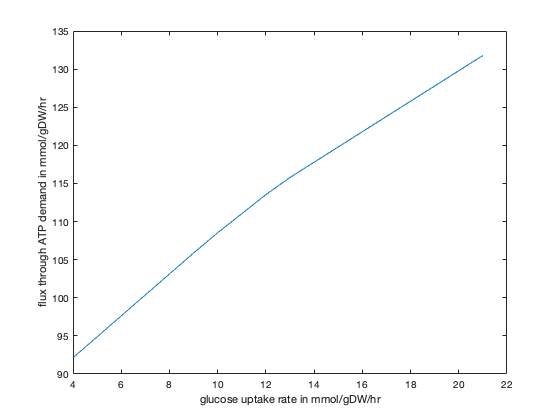

modelrobust = modelalter;
modelrobust = changeRxnBounds(modelrobust, 'EX_o2(e)', -17, 'b'); 
AtpRates = zeros(21, 1);
for i = 0:20
    modelrobust = changeRxnBounds(modelrobust, 'EX_glc(e)', -i, 'b');
    modelrobust = changeObjective(modelrobust, 'DM_atp(c)'); 
    FBArobust = optimizeCbModel(modelrobust, 'max'); 
    AtpRates(i + 1) = FBArobust.f;
end
plot(1:21, AtpRates)
xlabel('glucose uptake rate in mmol/gDW/hr')
ylabel('flux through ATP demand in mmol/gDW/hr')

#### Oxigeno

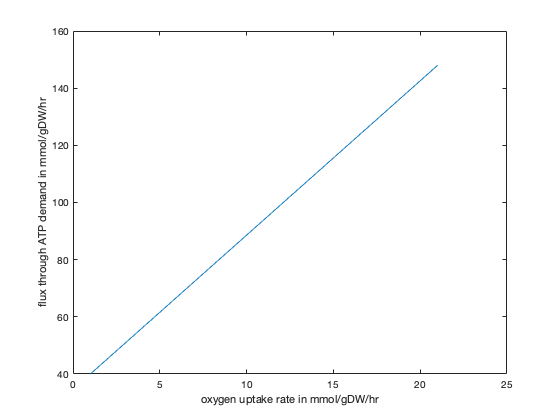

modelrobustoxy = modelalter;
modelrobustoxy = changeRxnBounds(modelrobustoxy,'EX_glc(e)', -20, 'b'); 
AtpRatesoxy = zeros(21, 1);
for i = 0:20
    modelrobustoxy = changeRxnBounds(modelrobustoxy, 'EX_o2(e)', -i, 'b'); 
    modelrobustoxy = changeObjective(modelrobustoxy, 'DM_atp(c)'); 
    FBArobustoxy = optimizeCbModel(modelrobustoxy, 'max'); 
    AtpRatesoxy(i + 1) = FBArobustoxy.f;
end
plot (1:21, AtpRatesoxy)
xlabel('oxygen uptake rate in mmol/gDW/hr') 
ylabel('flux through ATP demand in mmol/gDW/hr')

### 7. Análisis del plano de fase fenotípica

Mientras que el análisis de robustez analiza la robustez de la red variando solo un parámetro a la vez. El análisis del plano de fase fenotípica (PhPP) analiza la robustez de la red variando dos parámetros a la vez. Variaremos las tasas de consumo de glucosa y oxígeno dentro de dos bucles for y generaremos un gráfico 3D. 

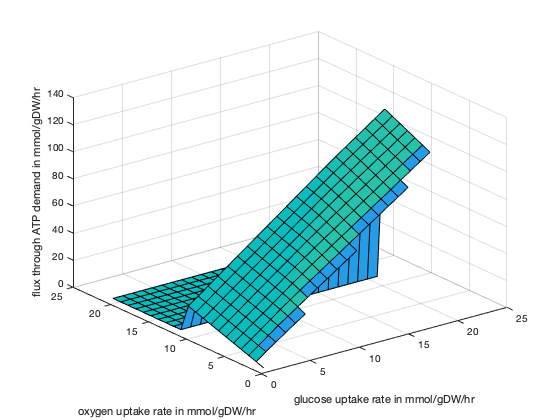

modelphpp = modelalter; 
ATPphppRates = zeros(21);
for i = 0:10
    for j = 0:20
        modelphpp = changeRxnBounds(modelphpp, 'EX_glc(e)', -i, 'b'); 
        modelphpp = changeRxnBounds(modelphpp, 'EX_o2(e)', -j, 'b'); 
        modelphpp = changeObjective(modelphpp, 'DM_atp(c)'); 
        FBAphpp = optimizeCbModel(modelphpp, 'max'); 
        ATPphppRates(i + 1,j + 1) = FBAphpp.f;
    end 
end
surfl(ATPphppRates) % 3d plot
xlabel('glucose uptake rate in mmol/gDW/hr') 
ylabel('oxygen uptake rate in mmol/gDW/hr') 
zlabel('flux through ATP demand in mmol/gDW/hr')

Plano en 2D

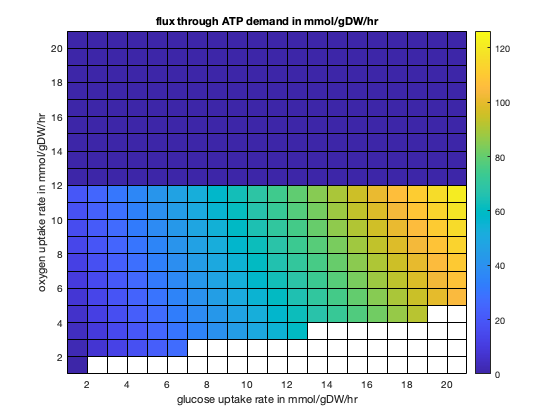

pcolor(ATPphppRates)
xlabel('glucose uptake rate in mmol/gDW/hr') 
ylabel('oxygen uptake rate in mmol/gDW/hr') 
title('flux through ATP demand in mmol/gDW/hr')
colorbar

### 8. Simulación de knockouts de genes

La realización de estudios de eliminación de genes permite el análisis de los genes knockout en el objetivo del modelo. Esto se puede hacer usando el comando `singleGeneDeletion` o el comando d`oubleGeneDeletion`. En `singleGeneDeletion`, todos los genes de la red se eliminan o las reacciones asociadas con una regla '`y`' (con la asociación GPR) con el gen especificado se limitan a estar inactivas, y se analiza el efecto en la reacción objetiva. Por el contrario, en `doubleGeneDeletion`, las eliminaciones de genes por pares están enlasadas.

Aquí, usaremos el '`DM_heme(c)`' como objetivo y realizaremos la eliminación de genes simples y dobles. 

modelknockout = model;
modelknockout = changeObjective(modelknockout, 'DM_heme(m)'); 
[grRatio, grRateKO, grRateWT, delRxns, hasEffect] = singleGeneDeletion_MitoModel(modelknockout);

grRateWT =           89.7381078359827


solKO = struct with fields:
    origStatText: []
               f: 88.3490337161115
              f0: NaN
              f1: 88.3490337161115
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0154009999999971
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 88.3490337161115
              f0: NaN
              f1: 88.3490337161115
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0188559999999995
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 88.3490337161114
              f0: NaN
              f1: 88.3490337161114
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0186369999999982
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 4.75045254763282e-31
              f0: NaN
              f1: 4.75045254763282e-31
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0209049999999991
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 74.1640206883592
              f0: NaN
              f1: 74.1640206883592
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0330020000000033
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 45.4545454545455
              f0: NaN
              f1: 45.4545454545455
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.017710000000001
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 8.53546881498921e-16
              f0: NaN
              f1: 8.53546881498921e-16
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0177909999999954
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 71.1889739584393
              f0: NaN
              f1: 71.1889739584393
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0156840000000003
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 62.5
              f0: NaN
              f1: 62.5
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0162419999999983
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7316242620116
              f0: NaN
              f1: 89.7316242620116
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0160720000000012
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0140740000000008
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.014485999999998
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 0
              f0: NaN
              f1: 0
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0132370000000037
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0264239999999987
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0359550000000013
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0295429999999968
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0385690000000025
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0296540000000007
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0342229999999972
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0155129999999986
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0133269999999968
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0207559999999987
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0134429999999952
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0123320000000007
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0148939999999982
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0141100000000023
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0187260000000009
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0186010000000039
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0175899999999984
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0151409999999998
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0140010000000004
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0137730000000005
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0150959999999998
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0126279999999994
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0128159999999937
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0122750000000025
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0118890000000036
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0124569999999977
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0150900000000007
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0144510000000011
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0154169999999993
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.015628999999997
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 80.6844590389869
              f0: NaN
              f1: 80.6844590389869
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0126300000000015
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 82.2374667878913
              f0: NaN
              f1: 82.2374667878913
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0126380000000026
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0129960000000011
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0166090000000025
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0134399999999957
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0139340000000061
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.6636877741875
              f0: NaN
              f1: 89.6636877741875
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0122919999999951
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 0
              f0: NaN
              f1: 0
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0145550000000014
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0124200000000059
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 62.5
              f0: NaN
              f1: 62.5
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.012239000000001
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0131140000000016
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.012397
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0137140000000002
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0151939999999939
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.018222999999999
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.022427
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.01705
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.016393
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.016998
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.017665
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.022631
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.016593
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.017824
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.026547
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.01808
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.014956
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.01264
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.012711
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.017217
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.014978
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.01563
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0142600000000001
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.01466
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.016236
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.014726
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.017649
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0191800000000001
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0337499999999999
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.030728
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0200790000000001
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0209140000000001
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0173580000000001
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.014394
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.023767
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.019679
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0194240000000001
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.027542
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.02054
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.023458
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0273019999999999
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0233989999999999
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.018931
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 59.3798218107611
              f0: NaN
              f1: 59.3798218107611
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0192060000000001
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 74.1640206883592
              f0: NaN
              f1: 74.1640206883592
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.02366
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.019754
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0176620000000001
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0262770000000001
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 54.9419039353012
              f0: NaN
              f1: 54.9419039353012
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0161579999999999
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.021412
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0300659999999999
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 0
              f0: NaN
              f1: 0
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0264350000000002
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0298660000000002
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 1.23683792704236e-15
              f0: NaN
              f1: 1.23683792704236e-15
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0195070000000002
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 82.2374667878913
              f0: NaN
              f1: 82.2374667878913
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.015091
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 82.2374667878913
              f0: NaN
              f1: 82.2374667878913
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.014373
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 82.2374667878913
              f0: NaN
              f1: 82.2374667878913
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0202070000000001
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 82.2374667878913
              f0: NaN
              f1: 82.2374667878913
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0225839999999999
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0305839999999997
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0269720000000002
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0177659999999999
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 89.7381078359827
              f0: NaN
              f1: 89.7381078359827
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0229540000000004
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 0
              f0: NaN
              f1: 0
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0204219999999999
           basis: []
          vars_v: []
               x: [225×1 double]


solKO = struct with fields:
    origStatText: []
               f: 0
              f0: NaN
              f1: 0
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0285030000000002
           basis: []
          vars_v: []
               x: [225×1 double]


La función (`singleGeneDeletion_MitoModel.m`) es la misma `singleGeneDeletion`, excepto que se comenta la parte de la transcripción para permitir la alineación de la solución según la matriz `model.genes`.

Analice qué genes son esenciales para la reacción '`DM_heme(c)`' a partir del output de `grRatio`. 

Para realizar la deleción de doble gen:

[grRatioDble, grRateKODble, grRateWTDble] = doubleGeneDeletion(modelknockout); 

Single deletion analysis to remove lethal genes
Single gene deletion analysis in progress ...
100%    [........................................]
286 non-lethal genes
Double gene deletion analysis
Total of 40755 pairs to analyze
Double gene deletion analysis in progress ...
Perc complete	CPU time


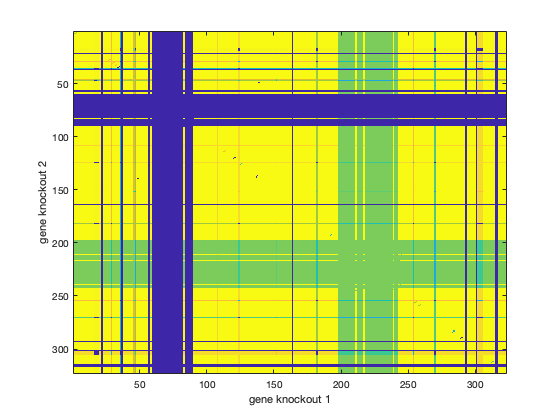

imagesc(grRatioDble)
xlabel('gene knockout 1')
ylabel('gene knockout 2')

### 9. Practica

Se identifico experimentalmente el fenotipo de diferentes condiciones de la mitocondria entre los cuales se encuentran:

- Estado fisiológico normal

- Condición diabética

- Condición isquémica

- Dieta baja en grasas alta en glucosa

- Dieta alta en grasas baja en glucosa

#### Estado fisiológico normal

modelnormal = model;
modelnormal = changeRxnBounds(modelnormal,'DM_atp(c)',7.5,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_acac(e)',-0.001,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_acac(e)',0,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_crvnc(e)',-0.156,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_crvnc(e)',-0.013,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_arachd(e)',-0.156,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_arachd(e)',-0.013,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_glc(e)',-0.875,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_glc(e)',-0.525,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_hb(e)',-0.001,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_hb(e)',0,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_hdca(e)',-1.250,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_hdca(e)',-0.1,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_lac-L(e)',-0.875,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_o2(e)',-39.1,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_o2(e)',-23.438,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdca(e)',-0.547,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdca(e)',-0.044,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdcea(e)',-4.141,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdcea(e)',-0.331,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdcya(e)',-0.547,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdcya(e)',-0.044,'u');
modelnormal = changeRxnBounds(modelnormal,'ATPtm',-32.6,'l');
modelnormal = changeRxnBounds(modelnormal,'ATPtm',32.6,'u');
modelnormal = changeRxnBounds(modelnormal,'CITRtm',-60,'l');
modelnormal = changeRxnBounds(modelnormal,'CITRtm',60,'u');
modelnormal = changeRxnBounds(modelnormal,'OCOAT1m',-16.9,'l');
modelnormal = changeRxnBounds(modelnormal,'OCOAT1m',16.9,'u');
modelnormal = changeRxnBounds(modelnormal,'SUCCt2m',-13.3,'l');
modelnormal = changeRxnBounds(modelnormal,'SUCCt2m',13.3,'u');

#### Condición diabética

modeldiab = model;
modeldiab = changeRxnBounds(modeldiab,'EX_acac(e)',-0.121,'l');
%modeldiab = changeRxnBounds(modeldiab,'EX_acac(e)',-0.020,'u');
modeldiab = changeRxnBounds(modeldiab,'EX_hb(e)',-0.106,'l');
modeldiab = changeRxnBounds(modeldiab,'EX_hb(e)',-0.016,'u');
modeldiab = changeRxnBounds(modeldiab,'EX_glc(e)',-0.644,'l');
modeldiab = changeRxnBounds(modeldiab,'EX_glc(e)',-0.386,'u');
modeldiab = changeRxnBounds(modeldiab,'C160CPT1',0.383,'l');
modeldiab = changeRxnBounds(modeldiab,'C160CPT1',0.4,'u');
modeldiab = changeRxnBounds(modeldiab,'C180CPT1',0.168,'l');
modeldiab = changeRxnBounds(modeldiab,'C180CPT1',0.183,'u');
modeldiab = changeRxnBounds(modeldiab,'C181CPT1',1.365,'l');
modeldiab = changeRxnBounds(modeldiab,'C181CPT1',1.380,'u');
modeldiab = changeRxnBounds(modeldiab,'C182CPT1',0.135,'l');
modeldiab = changeRxnBounds(modeldiab,'C182CPT1',0.151,'u');

#### Condición isquémica

modelische = model;
modelische = changeRxnBounds(modelische,'EX_o2(e)',-9.766,'l');
modelische = changeRxnBounds(modelische,'EX_o2(e)',-5.859,'u');
modelische = changeRxnBounds(modelische,'EX_glc(e)',-2,'l');
modelische = changeRxnBounds(modelische,'EX_glc(e)',-0.7,'u');
modelische = changeRxnBounds(modelische,'EX_acac(e)',-1.359,'l');
%modelische = changeRxnBounds(modelische,'EX_acac(e)',-0.140,'u');
modelische = changeRxnBounds(modelische,'EX_hb(e)',-1.171,'l');
modelische = changeRxnBounds(modelische,'EX_hb(e)',-0.110,'u');

#### Dieta baja en grasas alta en glucosa

modellowfat = model;
modellowfat = changeRxnBounds(modellowfat,'EX_glc(e)',-1.5,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_glc(e)',-0.875,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_arachd(e)',-0.047,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_arachd(e)',-0.013,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_crvnc(e)',-0.047,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_crvnc(e)',-0.013,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_hdca(e)',-0.375,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_hdca(e)',-0.1,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdca(e)',-0.164,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdca(e)',-0.044,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdcea(e)',-0.521,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdcea(e)',-0.331,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdcya(e)',-0.164,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdcya(e)',-0.044,'u');

#### Dieta alta en grasas baja en glucosa

modelhighfat = model;
modelhighfat = changeRxnBounds(modelhighfat,'EX_glc(e)',-0.263,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_glc(e)',-0.158,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_arachd(e)',-0.156,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_arachd(e)',-0.154,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_crvnc(e)',-0.036,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_crvnc(e)',-0.031,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_hdca(e)',-0.467,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_hdca(e)',-0.460,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdca(e)',-0.215,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdca(e)',-0.210,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdcea(e)',-1.179,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdcea(e)',-1.173,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdcya(e)',-0.159,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdcya(e)',-0.153,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_acac(e)',-0.324,'l');
%modelhighfat = changeRxnBounds(modelhighfat,'EX_acac(e)',-0.287,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_hb(e)',-0.109,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_hb(e)',-0.076,'u');

Utilizar las herramientas usadas anteriormente para concluir algo de estos modelos

## Bibliografia

- Orth et al, Nat Biotechnol. 2010 Mar;28(3):245-8

- Thiele et al, J Biol Chem. 2005 Mar 25;280(12):11683-95